# Prácticas de Control por Computador (3º GIERM, UMA)

## Práctica 8: Descripcion y control en espacio de estado I

#### **Tarea 1: Descripcion en espacio de estado**

El sistemas de la figura muestra un sistema mecanico de desplazamiento:

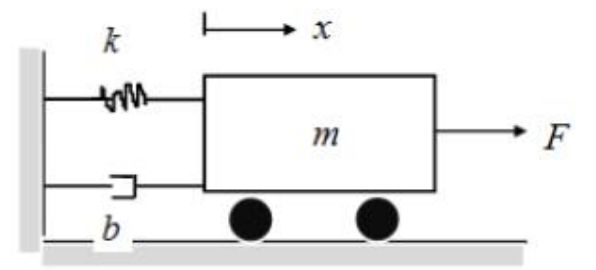

La ecuacion diferencial que describe su comportamiento dinamico es:


$$m \frac{d^2x}{dt^2}+b \frac{dx}{dt}+kx(t)=F(t)$$


**a)** Obtener la representacion en espacio de estado del sistema definiendo la posicion $x(t)$ y la velocidad $\frac{dx}{dt}$ como variables de estado para valores de $m=1, b=0.1, k=1$.

% Tu código aquí
m = 1;
b = 0.1;
k = 1;
sys1 = ss([0 1;(-k/m) (-b/m)],[0;1/m],[1 0],0)

sys1 =
 
  A = 
         x1    x2
   x1     0     1
   x2    -1  -0.1
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


`Resultado esperado:`

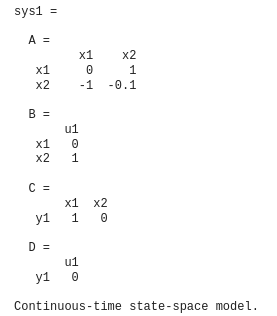

**b)** Implementar el sistema en Simulink a partir de las ecuaciones de estado y obtener la respuesta para una entrada escalon.

% Pega una captura de tu modelo simulink aqui

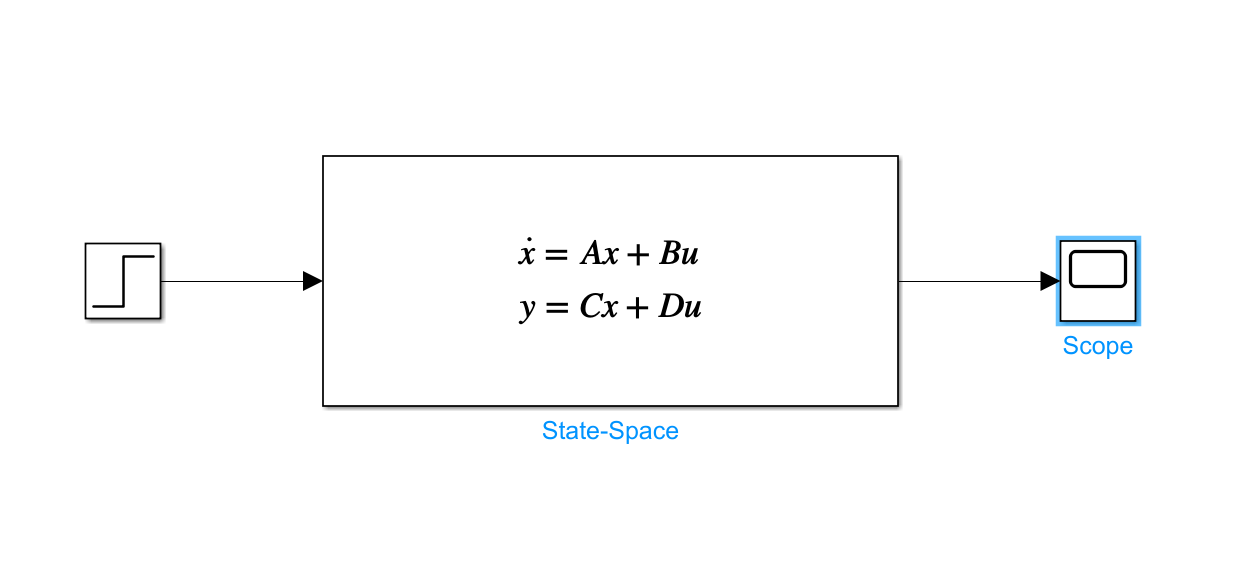

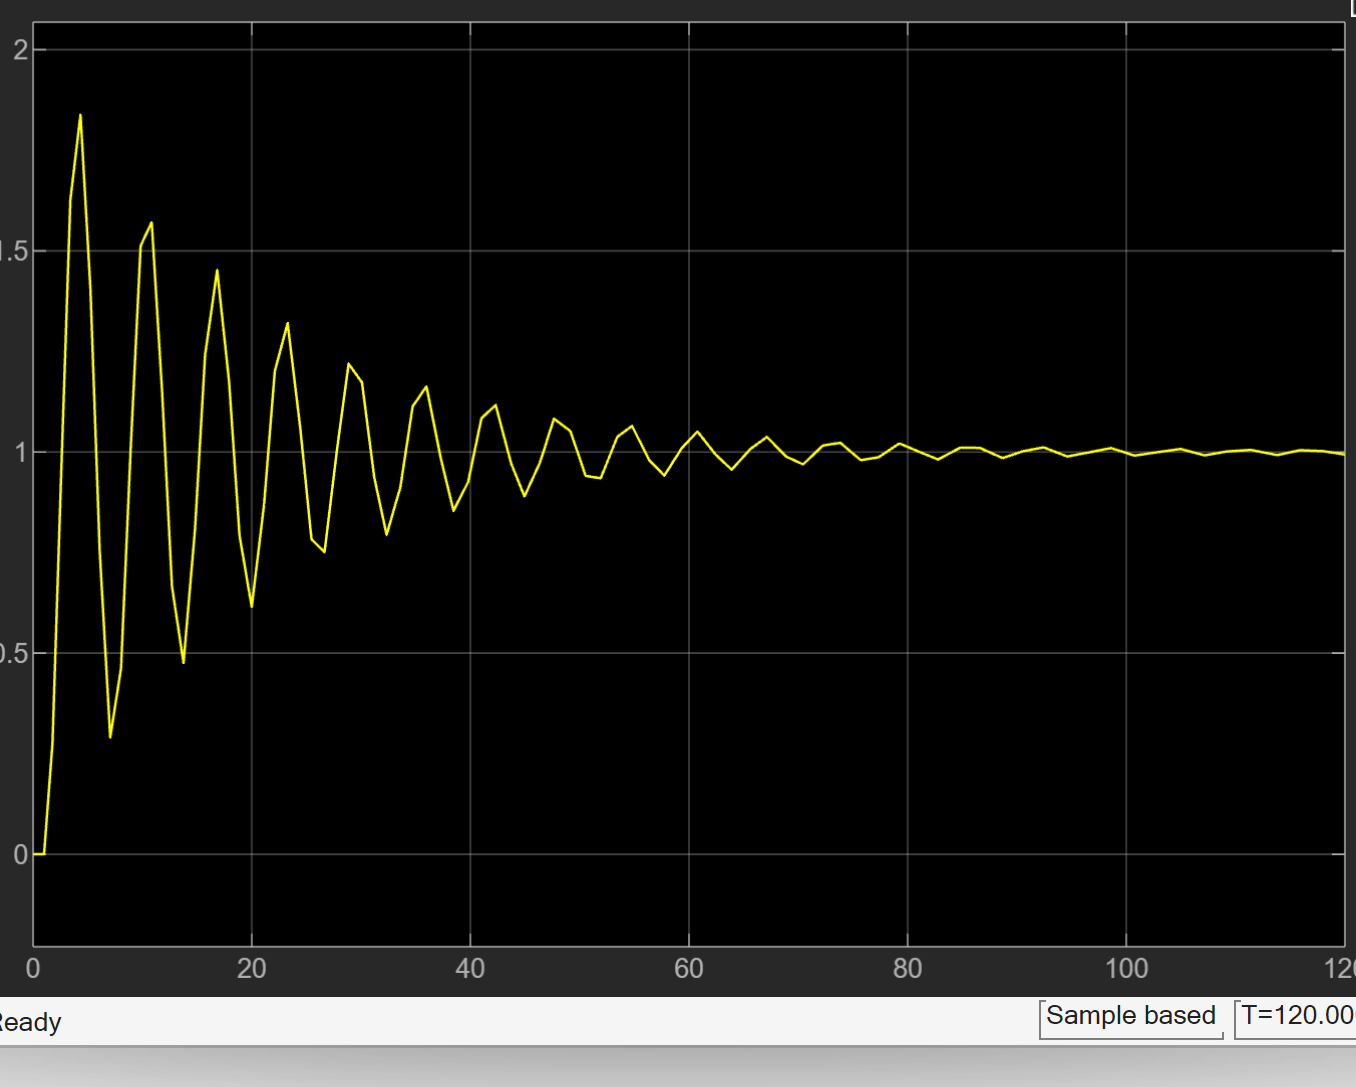

`Resultado esperado:`

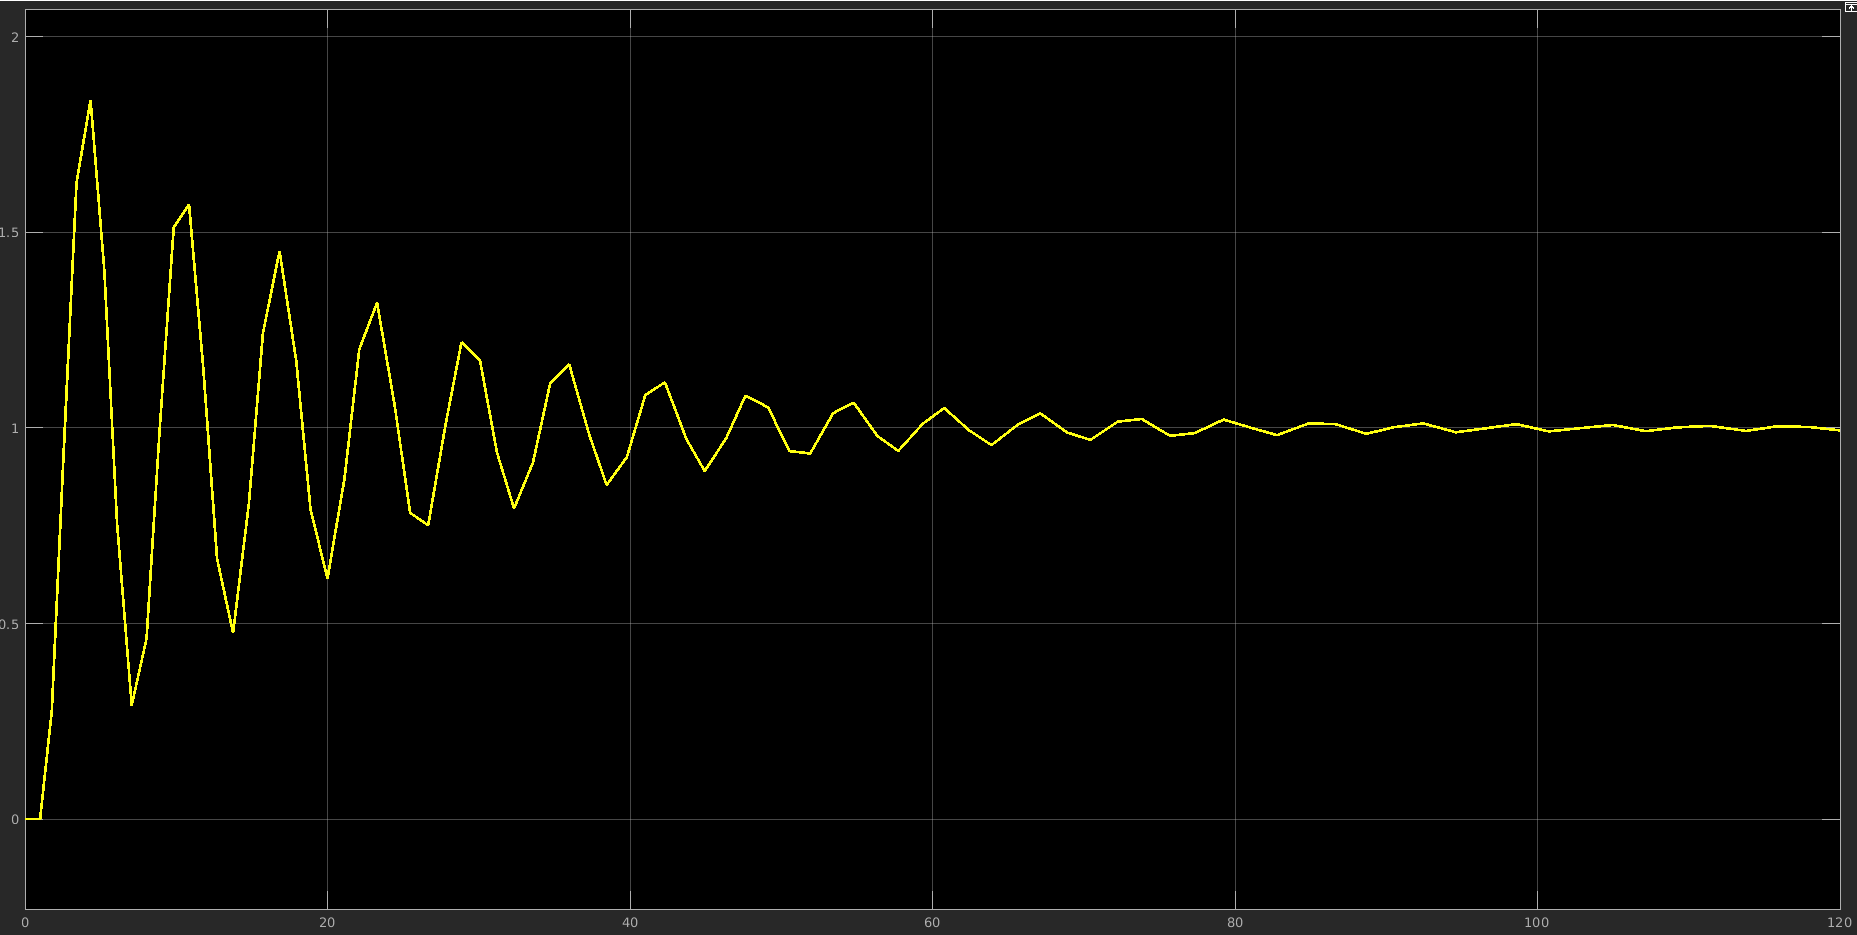

Podemos también representar la ecuación diferencial si no nos apetece meter la función de transferencia 

**c)** Deducirla estabilidad del sistema mecanico a partir del calculo de los autovalores de **A**. 

% Tu código aquí
eig(sys1.A) 

ans =   -0.0500 + 0.9987i
  -0.0500 - 0.9987i


Si los dos son negativos estable 

Limite de estabilidad es el 0 

Si uno es negativo y otro positivo no sabemos donde esta ahi habría que simular.

`Resultado esperado:`

**d)** Determinar las matrices de controlabilidad y observabilidad del sistema mecanico.

% Tu código aquí
Mc = [sys1.B sys1.A*sys1.B]

Mc =          0    1.0000
    1.0000   -0.1000


Mc = ctrb(sys1)

Mc =          0    1.0000
    1.0000   -0.1000


rank(Mc)

ans = 2

Mo = obsv(sys1)

Mo =      1     0
     0     1


rank(Mo) 

ans = 2

`Resultado esperado:`

**e)** Hallar la funcion de transferencia del sistema por conversion de formato $(\textbf{A},\textbf{B}, \textbf{C}, \textbf{D})$ a G(s).

% Tu código aquí
sys1_tf = tf(sys1)

sys1_tf =
 
         1
  ---------------
  s^2 + 0.1 s + 1
 
Continuous-time transfer function.
Model Properties


`Resultado esperado:`

**f)** Discretizar el sistema en espacio de estado anterior para valores de tiempo de muestreo de T=0.1s y T=1s y obtener la respuesta para una entrata escalon unitario de los sistemas en tiempo discreto..

% Tu código aquí
T1 = 0.1;
T2 = 1; 
sys1_T01 = c2d(sys1,T1)

sys1_T01 =
 
  A = 
             x1        x2
   x1     0.995   0.09934
   x2  -0.09934    0.9851
 
  B = 
             u1
   x1  0.004979
   x2   0.09934
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.


sys1_T1 = c2d(sys1,T2)

sys1_T1 =
 
  A = 
            x1       x2
   x1    0.555   0.8008
   x2  -0.8008   0.4749
 
  B = 
           u1
   x1   0.445
   x2  0.8008
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.


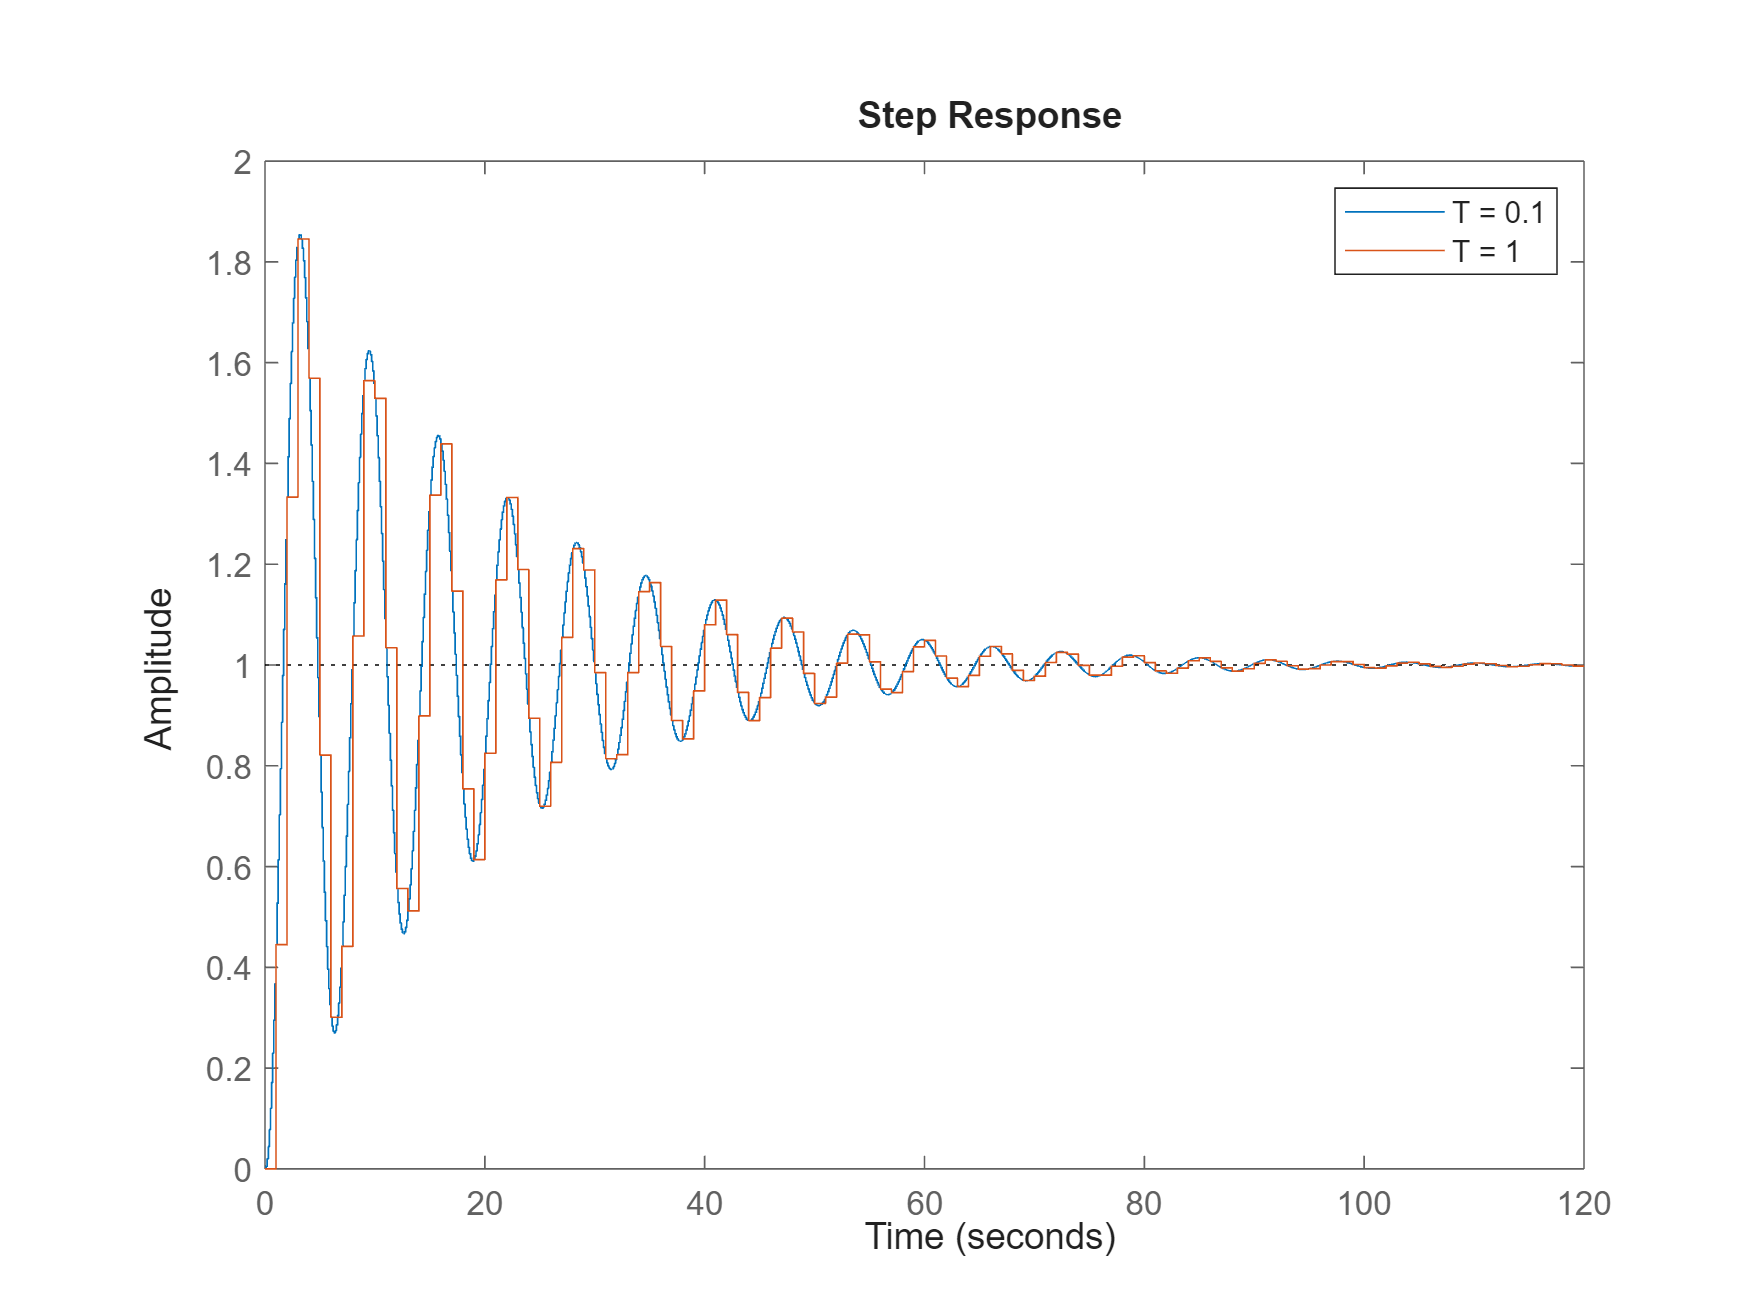

step(sys1_T01,sys1_T1)
legend('T = 0.1','T = 1')

`Resultado esperado:`

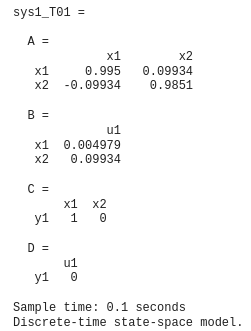

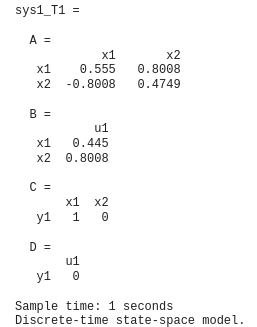

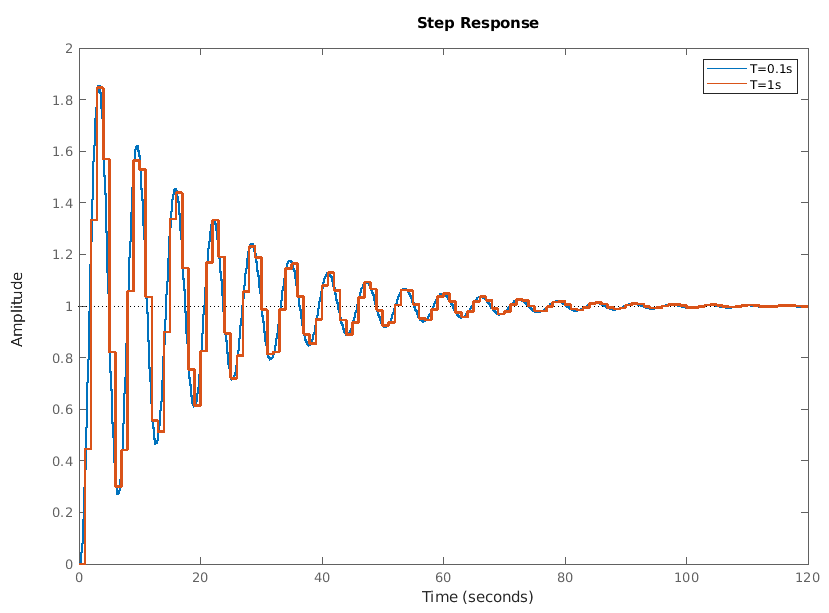

#### Tarea 2: Control en espacio de estado

La funcion de transferencia de un motor esta dada por:


$$G(s)=\frac{\theta(s)}{V(s)}=\frac{1}{s(s+2)}$$


donde $\theta(t)$ y $v(t)$ son la posicion angular y la tension de entrada respectivamente.

**a)** Obtener la representacion en espacio de estado para un vector de estado con compoentes posicion angular y velocidad angular.

% Tu código aquí
%Matlab te mete las variables que le da la gana. Es mejor meterla tu a
%mano y te quitas de problemas. 
sys2 = ss([0 1;0 -2],[0;1],[1 0],0)

sys2 =
 
  A = 
       x1  x2
   x1   0   1
   x2   0  -2
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


`Resultado esperado:`

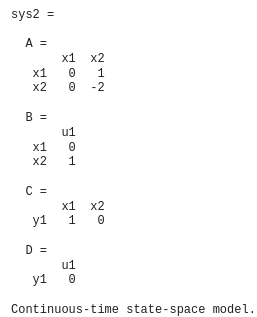

**b)** Se desea que el motor sea controlado en espacio de estado para que exhiba un comportamiento de segundo orden especificado por un par de polos deseados en $\mu_1,\mu_2=-2\pm5j$. Hallar el vector de ganacias ***K*** a partir de la formula de Ackermann.

% Tu código aquí

Mc = ctrb(sys2)

Mc =      0     1
     1    -2


rank(Mc)

ans = 2

polos=[-2+5*1j -2-5*1j]

polos =   -2.0000 + 5.0000i  -2.0000 - 5.0000i


K = acker(sys2.A,sys2.B,polos) 

K =     29     2


Mp = ((-sigma*pi)/(wd))

ts = 3/sigma

`Resultado esperado:`

**c)** Representar el sistema de control en Simulink y obtener la respuesta del sistema partiendo de condiciones iniciales de $\theta(0)=1$y $\dot{\theta}(0)=0.1$tanto en Matlab como en Simulink.

% Tu código aquí
sys2_bc = ss(sys2.A-sys2.B*K,[0;0],sys2.C,sys2.D)

sys2_bc =
 
  A = 
        x1   x2
   x1    0    1
   x2  -29   -4
 
  B = 
       u1
   x1   0
   x2   0
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


[Y,t,X] = initial(sys2_bc,[1,0.1])

Y =     1.0000
    0.9947
    0.9754
    0.9434
    0.9004
    0.8479
    0.7877
    0.7212
    0.6499
    0.5754


t =          0
    0.0230
    0.0461
    0.0691
    0.0921
    0.1151
    0.1382
    0.1612
    0.1842
    0.2072


X =     1.0000    0.1000
    0.9947   -0.5458
    0.9754   -1.1268
    0.9434   -1.6401
    0.9004   -2.0842
    0.8479   -2.4587
    0.7877   -2.7641
    0.7212   -3.0021
    0.6499   -3.1751
    0.5754   -3.2864


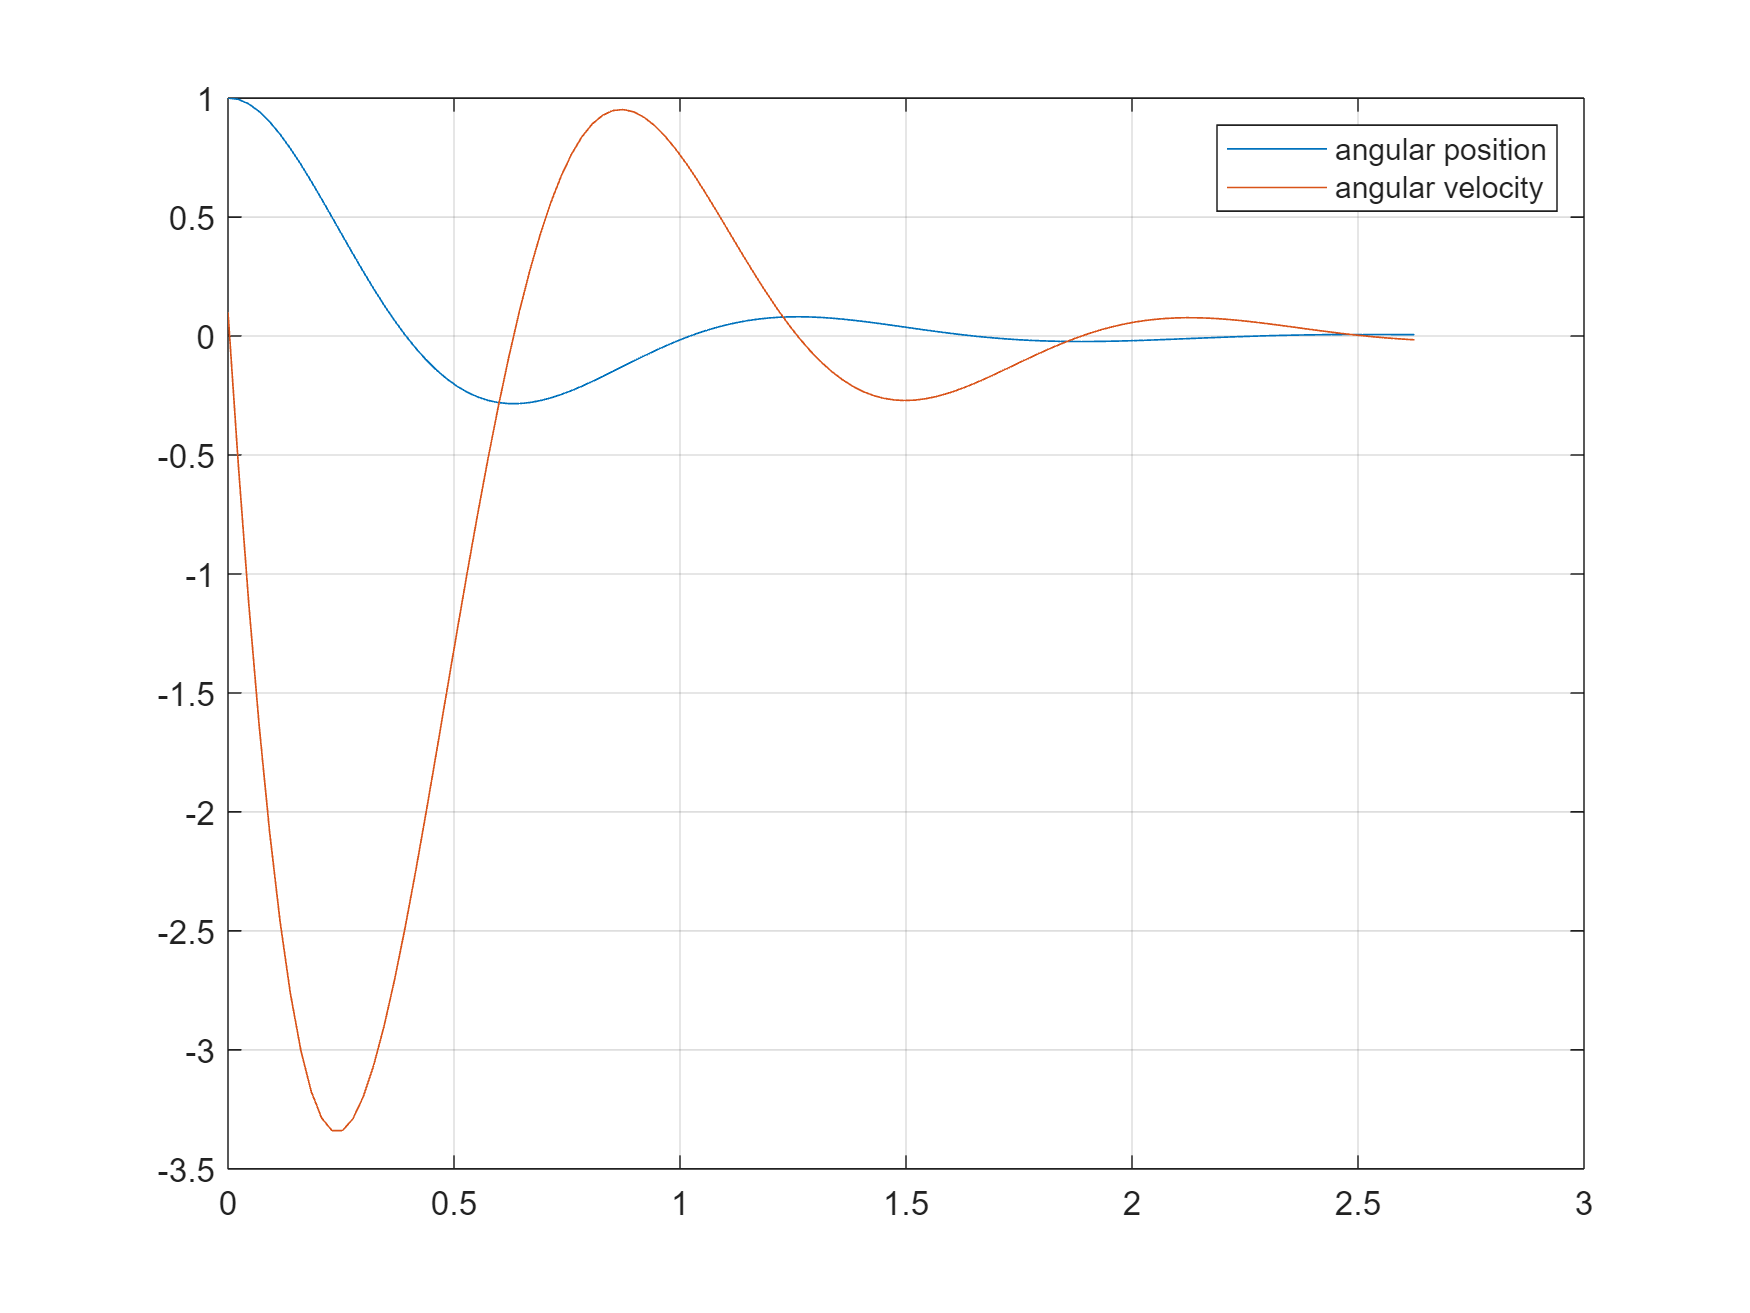

figure
plot(t,X);grid
legend('angular position','angular velocity')


% Pega una captura de tu modelo simulink aqui

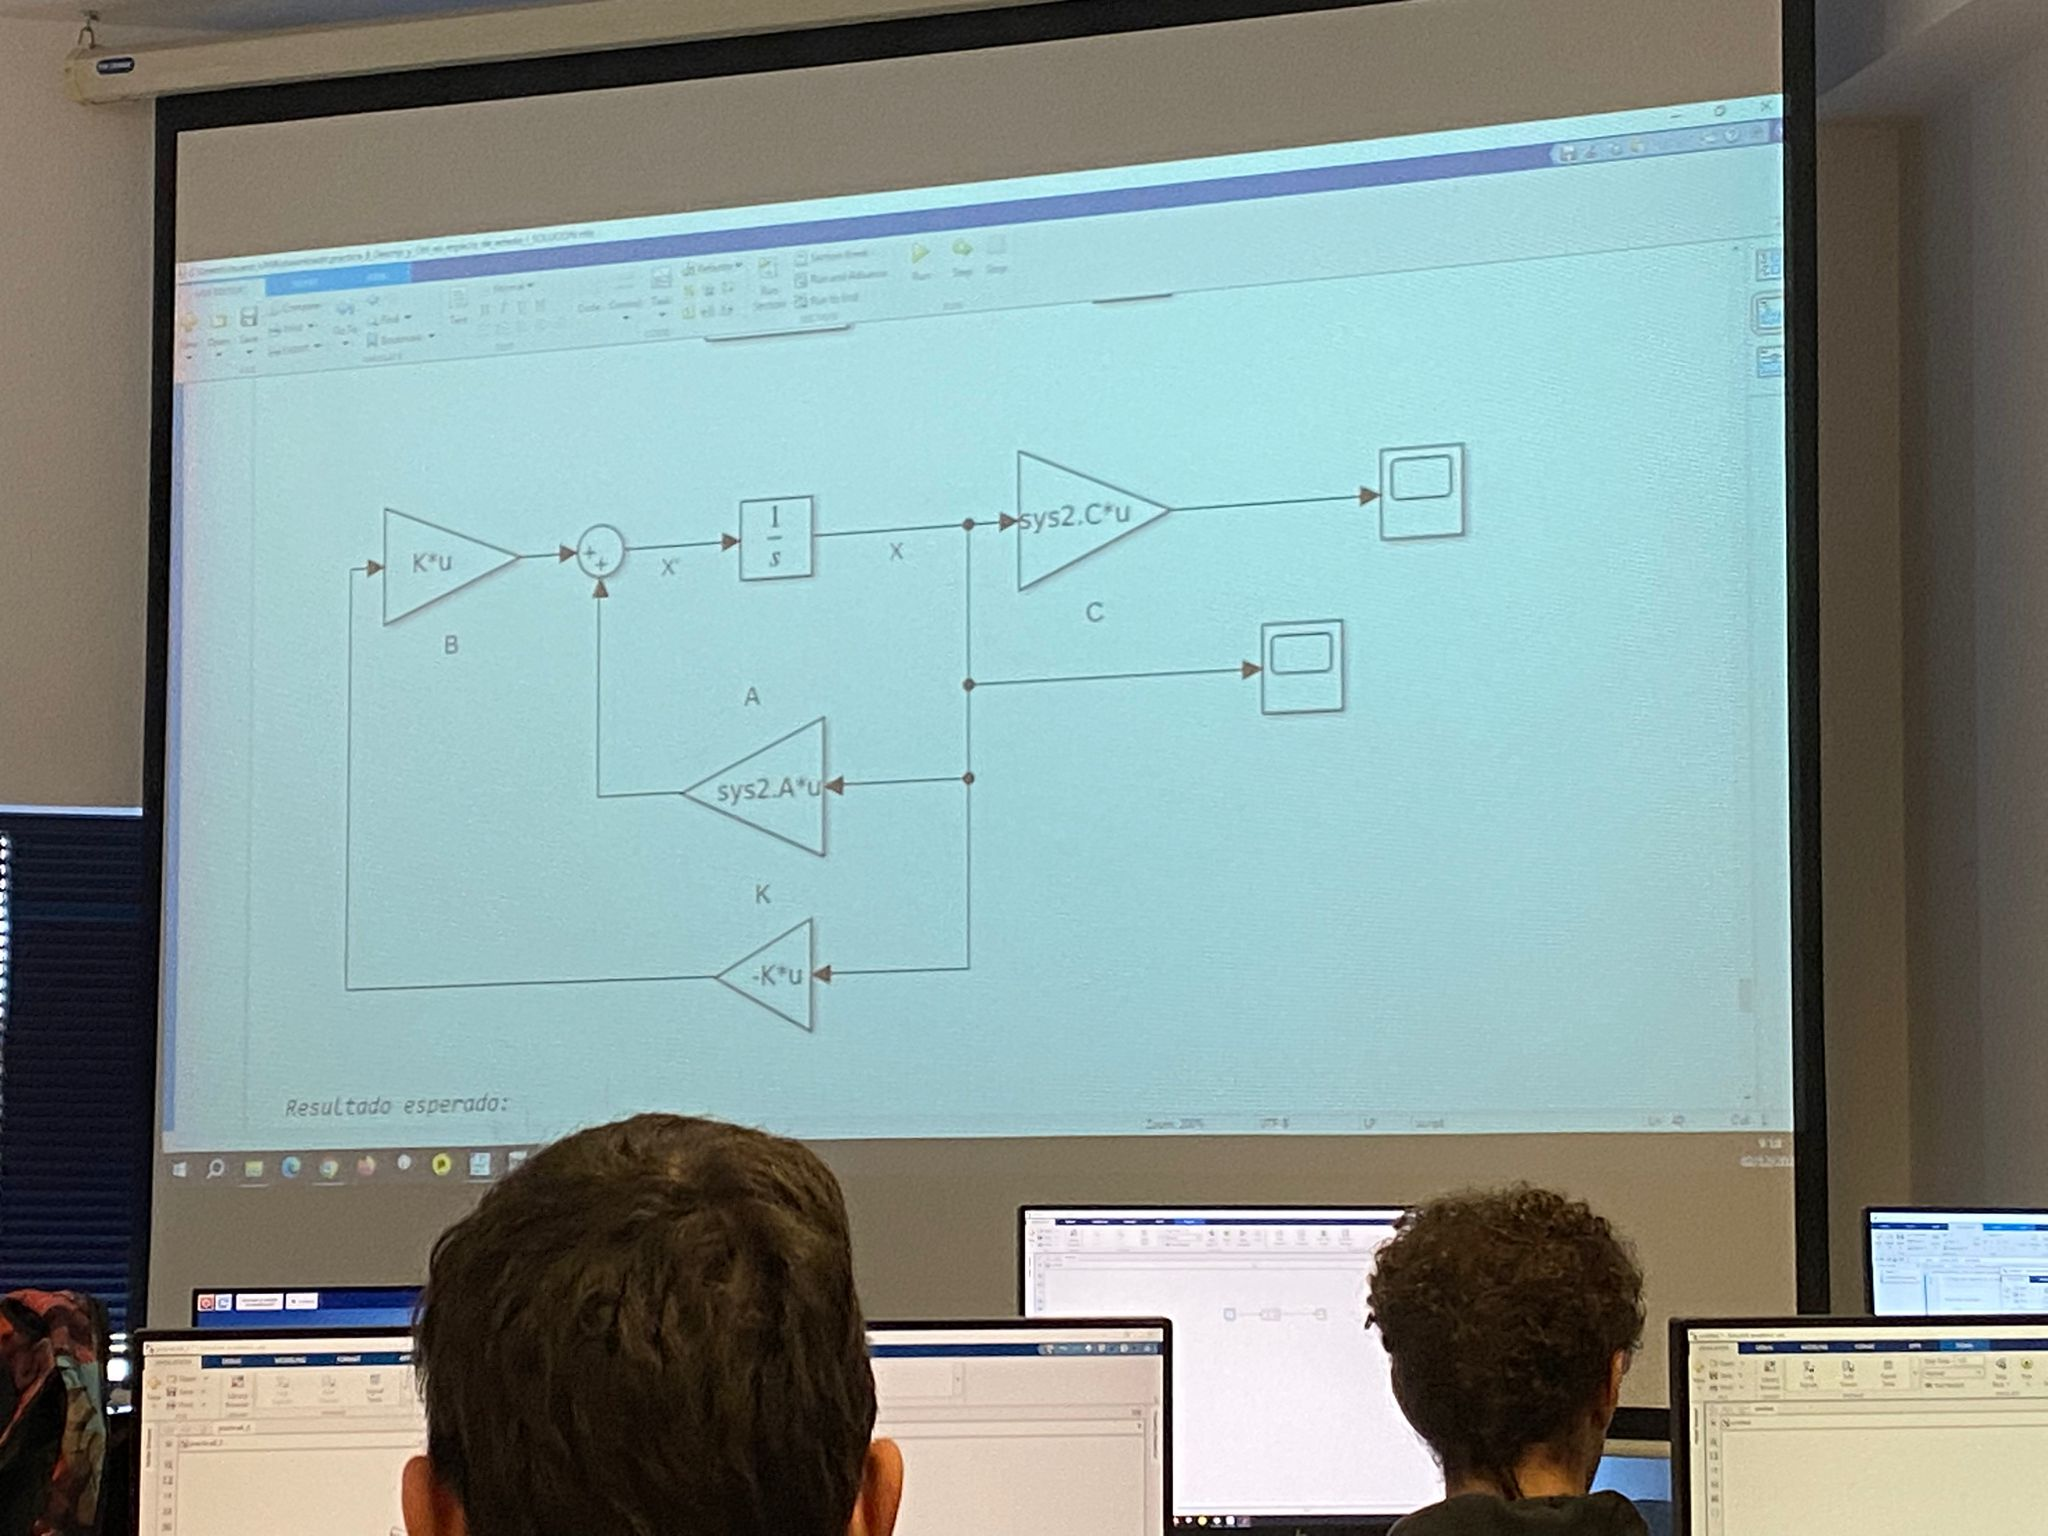

`Resultado esperado:`